# Bifurcation diagram for a quantum graph on a periodic hexagonal grid

## Construct the quantum graph and find the first few eigenfunctions

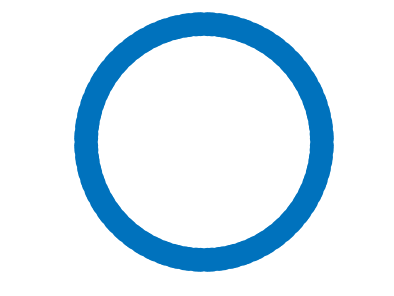

Created directory data/necklace/009.
Run number is 9.


tag='necklace';
Phi=quantumGraphFromTemplate('necklace','nPearls',64,'LString',1,'LPearl',pi/2);
dataDir = makeContinuationDirectory(Phi,tag);

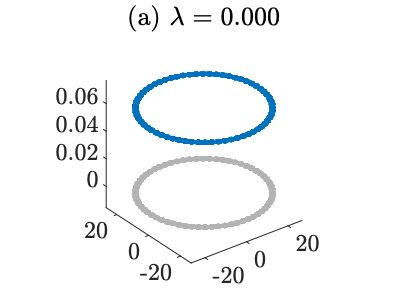

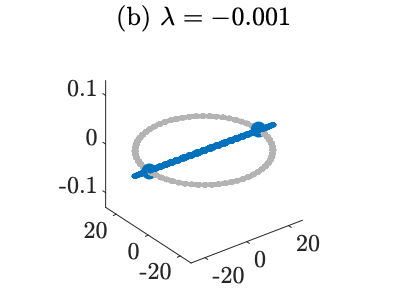

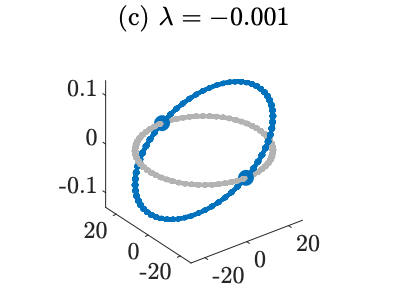

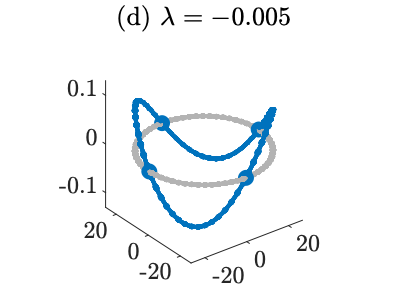

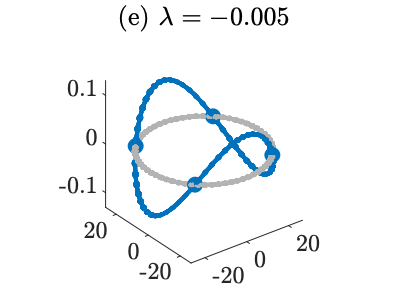

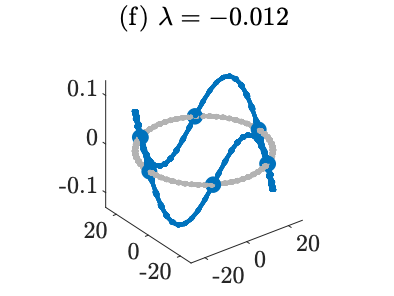

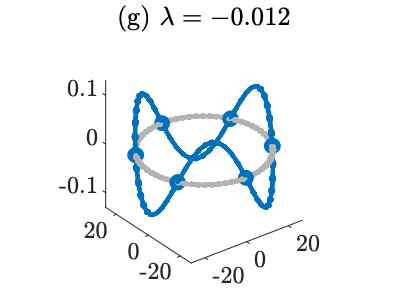

nToPlot=1;
nDoubles=3;
saveEigenfunctions(Phi,tag,dataDir,nToPlot,nDoubles);

Lambda0=-4;
options=continuerSet([],'LambdaThresh',-4.1,'NThresh',10,'plotFlag',false,'maxTheta',2);

syms z
f = 2*z^3;
fcns = saveNLSFunctionsGraph(dataDir,Phi,f);
branch1=continueFromEig(dataDir,1,options);

N threshold crossed.
Branch number 1.
Data saved to directory data/necklace/009/branch001.
No branching bifurcations found.


#### Compute a large-amplitude solution centered on both edges of a pearl, save it to a file, and compute its continuation

edges=[1 2];
signs=[1 1];
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/necklace/009/savedFunction.001.
File number is 1. 


direction=-1;
branch2=continueFromSaved(dataDir,filenumber,direction,options);

#### Compute a large-amplitude solution centered on one edge of a pearl, save it to a file, and compute its continuation

edges=1;
signs=1;
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/necklace/009/savedFunction.002.
File number is 2. 


branch3=continueFromSaved(dataDir,filenumber,direction,options);

#### Compute a large-amplitude solution centered on a string between two pearls, save it to a file, and compute its continuation

edges=3;
signs=1;
filenumber=saveHighFrequencyStandingWave(dataDir,Lambda0,edges,signs);

File saved to data/necklace/009/savedFunction.003.
File number is 3. 


branch4=continueFromSaved(dataDir,filenumber,direction,options);

Exited because distance between successive solutions below threshold.
Branch number 4.
Data saved to directory data/necklace/009/branch004.
Branching Bifurcation at solution number 19.


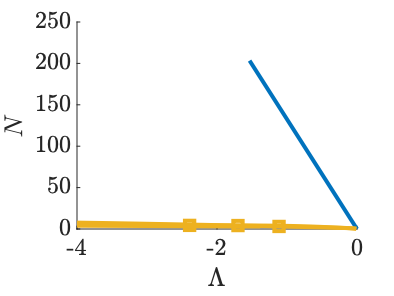

bifurcationDiagram(dataDir)

#### Compute branch that bifurcates from the upper of the two bifurcation points found on branch2

location=1;
direction=1;
branch5=continueFromBranchPoint(dataDir,branch2,location,direction,options);
bifurcationDiagram(dataDir)

#### Compute branch that bifurcates from thebifurcation point found on branch4

location=1;
direction=1;
branch6=continueFromBranchPoint(dataDir,branch4,location,direction,options);
bifurcationDiagram(dataDir)